# 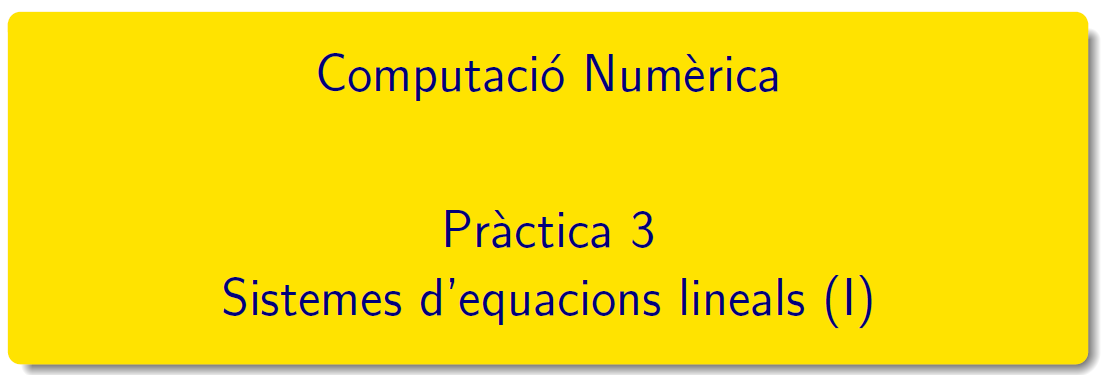

=======================================================================================

# Pràctica 3 - Primera part

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document  CN-tema2-QT2223.pdf que podeu trobar en el campus virtual. 

[Matrius de Matlab](https://es.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html) (resum de com treballar amb matrius) Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

#### **Exercici 1**. Àlgebra lineal

Calculeu  el determinant, la transposta, la inversa, els valors propis i els vectors propis de la matriu A definida per


$$A=\left(\begin{array}{rrr} 1 & 2 & 1\\ -2 & 7 & 3\\ 1 &-1 &10 \end{array}\right)$$


format shortG
A = [1 2 1; -2 7 3; 1 -1 10]

A =      1     2     1
    -2     7     3
     1    -1    10


detA = det(A)

detA =    114


transA = A'

transA =      1    -2     1
     2     7    -1
     1     3    10


invA = inv(A)

invA =       0.64035     -0.18421   -0.0087719
      0.20175     0.078947     -0.04386
     -0.04386     0.026316     0.096491


[V, D] = eig(A)

V =       0.91903     -0.34633      0.24387
      0.38888     -0.92036      0.67345
    -0.064465     -0.18162      0.69785


D =        1.7761            0            0
            0       6.8394            0
            0            0       9.3844


#### **Exercici 2**. Regla de Cramer

Escriu un script  i resol el sistema lineal següent fent ús de la regal de Cramer


$$\begin{array}{lcc}
		2x_1+4x_2+x_3 & = & 1\,,\\
		8x_1-x_2+3x_3 & = & 0\,,\\
		2x_1+5x_2 & = & 0\,.\\
	\end{array}$$


A=[2,4,1; 8,-1,3; 2,5 0]   %  matriu coeficients

A =      2     4     1
     8    -1     3
     2     5     0


b=[1;0;0]                  %  vector terme independent

b =      1
     0
     0


d=det(A)                   % determinant de la matriu

d =     36


Primera variable

A1=A; A1(:,1)=b, d1=det(A1), x1=d1/d

A1 =      1     4     1
     0    -1     3
     0     5     0


d1 =    -15


x1 =      -0.41667


Segona variable

A2=A; A2(:,2)=b, d2=det(A2), x2=d2/d

A2 =      2     1     1
     8     0     3
     2     0     0


d2 =      6


x2 =       0.16667


Tercera variable

A3=A; A3(:,3)=b, d3=det(A3); x3=d3/d

A3 =      2     4     1
     8    -1     0
     2     5     0


x3 =        1.1667


Solució numèrica de Matlab 

x=linsolve(A,b)

x =      -0.41667
      0.16667
       1.1667


### Mètodes directes

Documentació de Matlab: [Sistemas lineales](https://es.mathworks.com/help/matlab/math/systems-of-linear-equations.html) - [Systems of linear equations](https://es.mathworks.com/help/matlab/math/systems-of-linear-equations.html?lang=en)

MATLAB implementa mètodes directes a través dels operadors de divisió de matrius [`/`](https://es.mathworks.com/help/matlab/ref/mrdivide.html) i [`\`](https://es.mathworks.com/help/matlab/ref/mldivide.html), així com funcions com [`decomposition`](https://es.mathworks.com/help/matlab/ref/decomposition.html), [`lsqminnorm`](https://es.mathworks.com/help/matlab/ref/lsqminnorm.html), and [`linsolve`](https://es.mathworks.com/help/matlab/ref/linsolve.html).

#### **Exercici 3**. Matriu mal condicionada

Verifiqueu si un petit canvi a la matriu de coeficients del sistema lineal incueix grans canvis en la solució per als sistemes d'equaions següents


$$a) \left\{\begin{array}{rcrcr}7x&+&2y&=&6 \\ x&+&0.28y&=&2 \\ \end{array}\right. 
		\qquad	
		b) \left\{\begin{array}{rcrcr}7x&+&2y&=&6 \\ x&+&0.285y&=&2 \\ \end{array}\right.$$


A = [7 2; 1 0.28]

A =             7            2
            1         0.28


b = [6;2]

b =      6
     2


x = A\b

x =            58
         -200


A2 = [7 2; 1 0.285]

A2 =             7            2
            1        0.285


x2 = linsolve(A2, b)

x2 =           458
        -1600


C = abs(A-A2), dA = norm(C,'inf'), eA=dA/norm(A,'inf')*100

C =             0            0
            0        0.005


dA =         0.005


eA =      0.055556


abs(x-x2)

ans =           400
         1400


dx = norm(x-x2,'inf'), ex=dx/norm(x)*100

dx =          1400


ex =         672.3


cond(A),cond(A2),det(A),det(A2)

ans =          1352


ans =         10816


ans =         -0.04


ans =        -0.005


#### Exercici 4.  Matrius i vectors predefinits en MATLAB®

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$   

- Amb zeros a  totes les seves components

a = zeros(51)

a =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

b = zeros(51, 1)

b =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


- Amb uns a les seves components

I = eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


- Amb nombres al·leatòris uniformes de l'interval [-2,2]

a=-2; b=2;
U = a+(b-a)*rand(1,10000)

U =       -1.3847       1.8472        1.505    -0.045483     -0.37169      -1.4937       1.7017      -1.9777      -1.2544     -0.70376      -1.7993      -1.4219      0.91748    -0.070882     -0.64774      -1.0529     -0.19655      -1.2582     -0.70298     -0.94411       1.3203      0.78544     -0.66585      0.32093     -0.84865     -0.94412     -0.96039      0.70832     0.079306       -1.693      -1.7766     -0.96509     -0.24029     -0.86284      0.71507       1.7983       1.0958      0.54456       1.0143      0.98727      0.34412       1.0922     -0.43005      0.42116      -1.0103     -0.83919      -1.9227     -0.61076      -1.4328     -0.35386


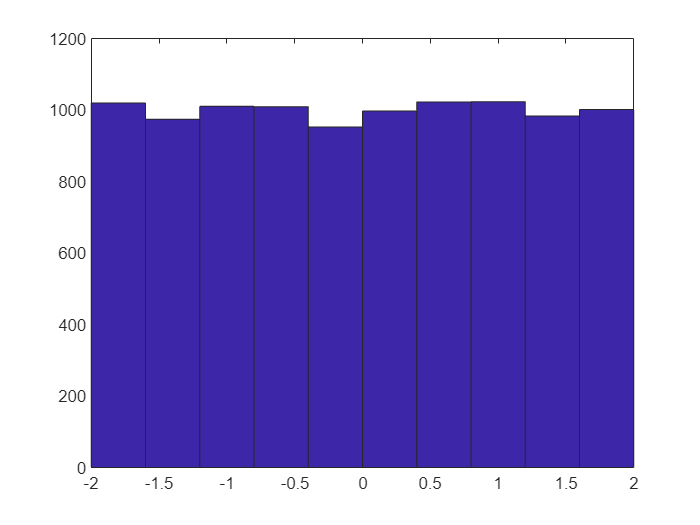

hist(U)

- Amb nombres al·leatòris normals amb $\mu = 0$ i $\sigma = 1$

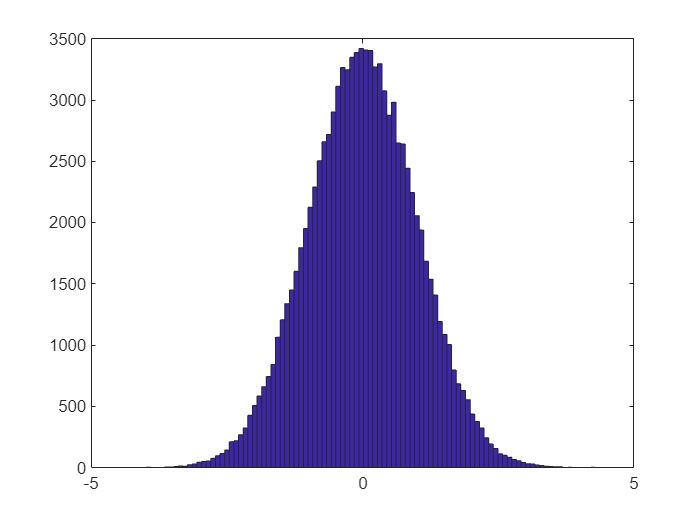

N=randn(1,100000); hist(N,100)

#### Exercici 5.  Sistemes triangulars superiors

Genereu un script en Matlab per trobar la solució d'un sistema lineal triangular superior pel mètode de substiució enrera. 

**JOC DE PROVES**

Resoleu els següents sistemes lineals:


$${\text a)}\ \left\{\begin{array}{rcr}
	3x-2y+z-t&=&8 \\ 4y-z+2t&=&-3\\ 2z+3t&=&11\\5t&=&15\end{array}\right.$$


U=[3 -2 1 -1; 0 4 -1 2; 0 0 2 3; 0 0 0 5]; b=[8;-3;11;15]

b =      8
    -3
    11
    15


n = 4

n =      4


x = zeros(n,1);
for k = n:-1:1
j = k+1:n;
x(k) = (b(k) - U(k,j)*x(j))/U(k,k);
end
x

x =      2
    -2
     1
     3


b)  Definiu la matriu  $U=\left(u_{ij}\right)_{15\times 15}$ i el vector  $b=(b_{i})_{15\times 1}$ com  $u_{ij}=\left\{\begin{array}{rr} \cos (ij) & i\leq j\,,\\ & \\ 0 & i>j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=\tan (i)$

#### Exercici 6.  Sistemes triangulars inferiors

Genereu un script en Matlab per trobar la solució d'un sistema lineal triangular inferior pel mètode de substiució endavant. 

**JOC DE PROVES**

Resoleu els següents sistemes lineals:


$${\text c)}\ \left\{\begin{array}{lcr}
	5x&=&-10 \\ x+3y&=&4\\ 3x+4y+2z&=&2\\-x+3y-6z-t&=&5\end{array}\right.$$


d) Definiu la matriu  $l=\left(l_{ij}\right)_{20\times 20}$ i el vector  $b=(b_{i})_{20\times 1}$ com  $l_{ij}=\left\{\begin{array}{rr} i+j & i\geq j\,,\\ & \\ 0 & i<j\,, \end{array}\right.
\qquad\mbox{i}\qquad b_{i1}=i\,.$

#### Exercici 7.  Eliminació gaussiana

Genereu un script de Matlab per trobar la solució d'un sistema lineal Ax=b pel mètodes d'eliminació gaussiana

** JOC DE PROVES**


$$e)\quad  A=\left (\begin{array}{rrrr}
		10 & -7 & 0 &  1\\
		-3 &  2 & 6 &  0\\
		5 & -1 & 5 &  0\\
		-1 &  0 & 2 & -1
		\end{array} \right)\quad\quad
	b=\left( \begin{array}{r} 7\\4\\6\\-3\end{array} \right).$$



$$f) \quad A=\left (\begin{array}{rrrr}
		 6 & -2  & 2 & 4\\
		12 & -4  & 2 & 2\\
		 3 & -13 & 9 & 3\\
		-6 &  4 & 1 & -18
	\end{array} \right)\quad\quad
	b=\left( \begin{array}{r} 12\\34\\27\\-38\end{array} \right).$$


g) Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$ com  $a_{ij}=\left\{\begin{array}{rl} (-1)^{i} &\ i=j\,,\\ & \\ 2 &\ 1\le|i-j|\le 2\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=i\,.$

### Mètodes compactes

#### Factoritzacions en Matlab®

Consulteu [LU, Txoleski i QR](https://es.mathworks.com/help/matlab/math/factorizations.html)

#### Exercici 8. Descomposició LU

Trobeu la descomposició LU de la matriu del sistema d'equacions lineals A i després resoleu el sistema d'equacions lineals Ax=b.


$$a) \qquad (A\,\vert\,b)=\left (
	\begin{array}{rrr|r}
		1 & 6 & 0\  & \ 3\\
		2 & 1 & 0\  & \ 1\\
		0 & 2 & 1\  & \ 1
	\end{array}\right )$$



$$b)\quad	(A\,\vert\,b)=\left ( \begin{array}{rrrr|r}
		6 & -2 & 2 & 4\ &\  0\\
		12& -8 & 4 & 10\  &\  -10\\
		3 & -13 & 3 & 3\  &\  -39\\
		-6 & 4 & 2 & -18\  &\  -16
	\end{array}\right ),$$


A=[6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]

A =      6    -2     2     4
    12    -8     4    10
     3   -13     3     3
    -6     4     2   -18


b=[0;-10;-39;-16]

b =      0
   -10
   -39
   -16


[L, U, P] = lu(A)

L =             1            0            0            0
         0.25            1            0            0
         -0.5            0            1            0
          0.5     -0.18182     0.090909            1


U =            12           -8            4           10
            0          -11            2          0.5
            0            0            4          -13
            0            0            0      0.27273


P =      0     1     0     0
     0     0     1     0
     0     0     0     1
     1     0     0     0


    
$$c)\quad \left\{ \begin{array}{rcrcrcrcr}
	6x_1 &+& 2x_2 &-& x_3&-& x_4&=&0\\
	2x_1 &+& 4x_2 &+& x_3& & &=&7\\
	-x_1 &+& x_2 &+& 4x_3 &-& x_4 &=&-1\\
	-x_1 & & &-& x_3&+&3x_4&=&-2
	\end{array}\right.$$


% primer pas Ly=Pb
y = inv(L)*P*b

y =           -10
        -36.5
          -21
      0.27273



% segon pas Ux=y
x = zeros(n,1);
n = 4

n =      4


for k = n:-1:1
j = k+1:n;
x(k) = (y(k) - U(k,j)*x(j))/U(k,k);
end
x

x =             1
            3
           -2
            1


% control:: vector residu
r = b-A*x

r =    1.7764e-15
            0
            0
  -3.5527e-15


#### Exercici 9. Inversa d'una matriu a partir de la descomposició LU


$$	a)\quad  A=\left ( \begin{array}{rrrr}
	6 & 2 & 1 & -1 \\
	2 & 4 & 1 & 0 \\
	1 & 1 & 4 & -1 \\
	-1 & 0 & -1 & 3
	\end{array}\right )$$$$



$$b)\quad A=\left(\begin{array}{cccc}
		1&2&3&4\\1&4&9&16\\1&8&27&64\\1&16&81&216\end{array}\right)$$


#### Exercici 10. Mètode QR

Trobeu la descomposició QR de la matriu del sistema d'equacions lineals A i després resoleu el sistema d'equacions lineals AX=b següents


$$a)\ \left\{ \begin{array}{rcr}
			6x_1 + 2x_2 - x_3 - x_4&=&0\\
			2x_1 + 4x_2 + x_3 &=&7\\
			-x_1 + x_2 + 4x_3 - x_4 &=&-1\\
			-x_1 - x_3+3x_4&=&-2
		\end{array}\right.$$



$$b)\ \left\{ \begin{array}{rcr}
			0.05x_1+0.07x_2+0.06x_3+0.05x_4&=&0.23\\
			0.07x_1+0.10x_2+0.08x_3+0.07x_4&=&0.32\\
			0.06x_1+0.08x_2+0.10x_3+0.09x_4&=&0.33\\
			0.05x_1+0.07x_2+0.09x_3+0.10x_4&=&0.31
			\end{array}\right.$$


`Document preparat per M. Àngela Grau Gotés 1 de març de 2023`